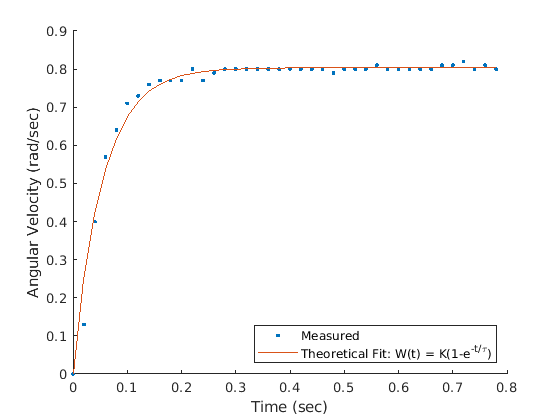

D = readmatrix("calibration_data.csv");
time = linspace(0,.02*(length(D)-1),length(D));
truncate=1:40;
D_trunc = D(truncate,2);
time_trunc = time(truncate);
K = 0.8035;
tau = 0.05451;
clf;hold on
plot(time(truncate),D(truncate,2),".")
plot(time(truncate),K*(1-exp(-time_trunc/tau)))
xlabel("Time (sec)")
ylabel("Angular Velocity (rad/sec)")
legend(["Measured", "Theoretical Fit: W(t) = K(1-e^{-t/\tau})"], "Location", "southeast")

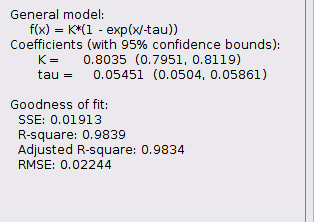

step = 300; %???
K = 0.8035 / step

K = 0.0027

tau = 0.05451

tau = 0.0545